# Hypothesis testing

clc;
close all;
clear variables;

## Parameters

ma = [3; -1]; 
mb = [10; -4];

sigma_a = [1.7; 3];
sigma_b = [3; 1.4];

rho_a = -0.6;
rho_b = 0.7;

num_a = 5000;
sum_b = 5000;

## Samples

A = Samples(ma, sigma_a, rho_a,  num_a);
B = Samples(mb, sigma_b, rho_b, sum_b);

## Plotting


figure();
grid on; hold on; axis equal;
labels = {};

A.plot('b.'); labels{end+1} = 'A';
B.plot('r.'); labels{end+1} = 'B';

title('Samples');
xlabel('$x_1$', "Interpreter","latex")
ylabel('$x_2$', "Interpreter","latex")

syms x_1 x_2 real
X = [x_1; x_2];

line_width = 2;

### Bayes' test of least error


$$h(X) = -ln\left(\frac{f_1}{f_2}\right) = ln\left(\frac{P_1}{P_2}\right)$$


P = [0.5; 0.5];

threshold = log(P(1) / P(2));
h = -log(A.pdf_sym(X) / B.pdf_sym(X));
fimplicit(h == threshold, 'Color', 'g', 'LineWidth', line_width)
labels{end+1} = '$h(X) == 0$';


$$f(X) = const$$


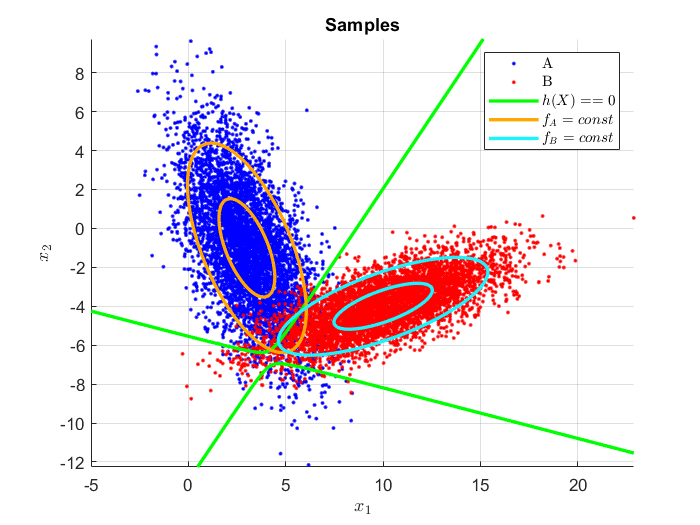

for const_pdf_val = [0.2 0.7]
    fimplicit(exp(-0.5 * (X - A.M)' * A.cov_mat ^ (-1) * (X - A.M)) == const_pdf_val, 'Color', '#FFA600', 'LineWidth', line_width)
    fimplicit(exp(-0.5 * (X - B.M)' * B.cov_mat ^ (-1) * (X - B.M)) == const_pdf_val, 'Color', '#1AF4FF', 'LineWidth', line_width)
end

labels{end+1} = '$f_A = const$';
labels{end+1} = '$f_B = const$';

leg = legend(labels);
set(leg,'Interpreter','latex');

% TODO Razdovojiti sliku sa d^2 i sliku sa h(X)

## Error estimation

### Histogram

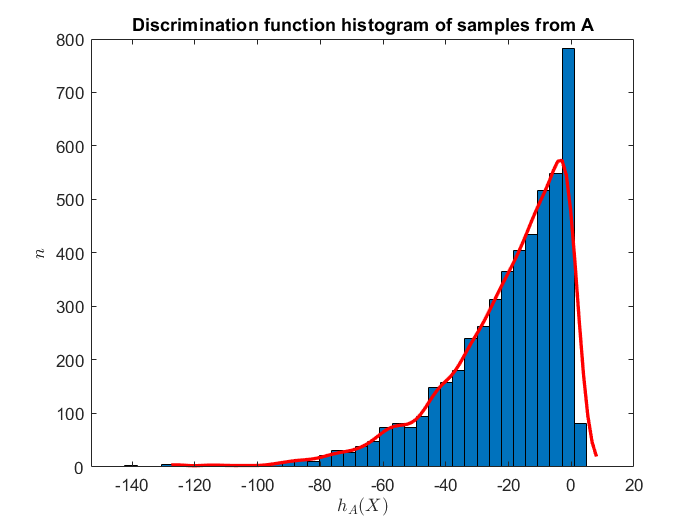

h_a = A.discrimination_function(B, 1);
n_bins = 40;
distribution_name = 'kernel';


figure();
histfit(h_a, n_bins, distribution_name);

title('Discrimination function histogram of samples from A')
xlabel('$h_A(X)$', "Interpreter","latex")
ylabel('$n$', "Interpreter","latex")

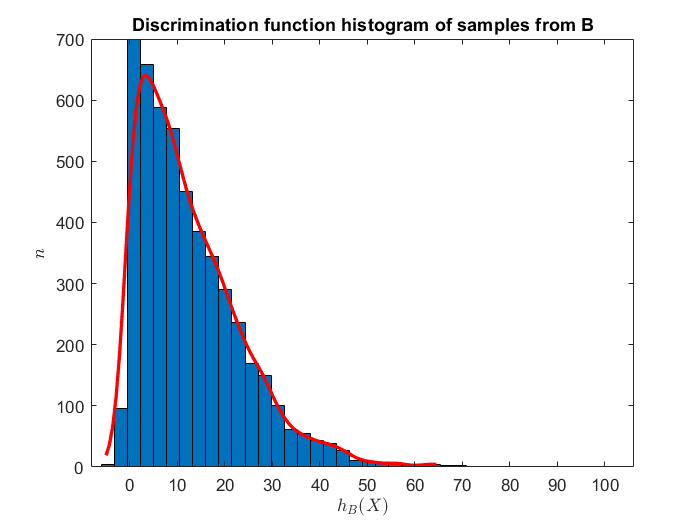

h_b = B.discrimination_function(A, 2);

figure();
histfit(h_b, n_bins, distribution_name);
title('Discrimination function histogram of samples from B')
xlabel('$h_B(X)$', "Interpreter","latex")
ylabel('$n$', "Interpreter","latex")

### PDF approximation

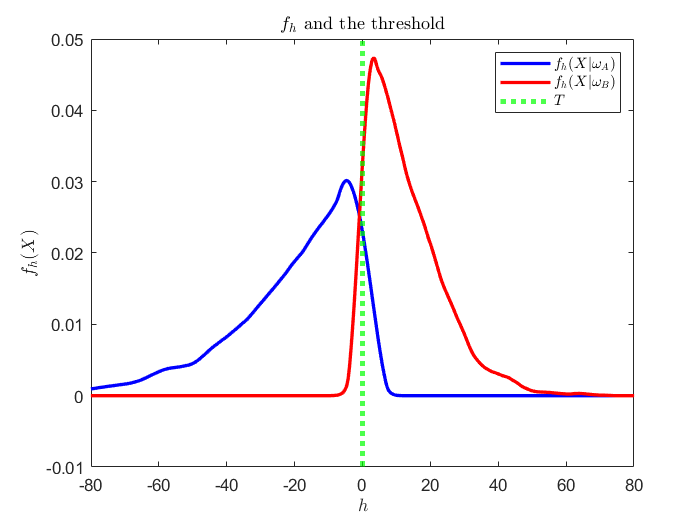

x_a = (-110:0.001:110)';
[y_a, fitobject_a] = approximate_pdf(h_a, x_a);

x_b = x_a;
[y_b, fitobject_b] = approximate_pdf(h_b, x_b);

figure();
plot(fitobject_a, 'b');
hold on;
plot(fitobject_b, 'r');

xline(threshold, 'g:', 'LineWidth', 3)
set(findall(gca, 'Type', 'Line'),'LineWidth', line_width);

legend('$f_h(X|\omega_A)$', '$f_h(X|\omega_B)$', '$T$', "Interpreter","latex")
xlim([-80, 80])
title("$f_h$ and the threshold", "Interpreter","latex")
xlabel("$h$", "Interpreter","latex")
ylabel("$f_h(X)$", "Interpreter","latex")


eps_1 = integrate(fitobject_a, max(x_a), threshold);
eps_2 = integrate(fitobject_b, threshold, min(x_b));

eps_1 * P(1)

ans = 0.0422

eps_2 * P(2)

ans = 0.0351

length(h_a(h_a > threshold)) / length(h_a)

ans = 0.0544

length(h_b(h_b < threshold)) / length(h_b)

ans = 0.0414